Входные параметры

close all;
clear variables;

#### 1.1 Исходные данные

% параметры волны
f = 400*10^6;
c = 3*10^8;
lambda = 10000; % 0.75 м %%% убрать 
phi_grad = 0;

% константы
k = 2*pi;
eta = 120*pi;
gamma = 1.781072417990;

#### 1.3. Расчет координат точек исходной фигуры

% % точки оснвого конутра
% pl_x(1) = 0;
% pl_z(1) = 0;
% pl_x(2) = 0;
% pl_z(2) = 11000;
% pl_x(3) = 11000;
% pl_z(3) = 11000;
% pl_x(4) = 11000;
% pl_z(4) = 0;
% 
% % точки вспомогат контура
% d_as = 100;
% pli_x(1) = d_as;
% pli_z(1) = 0;
% pli_x(2) = d_as;
% pli_z(2) = pl_z(2) - d_as;
% pli_x(3) = pl_x(3) - d_as;
% pli_z(3) = pl_z(3) - d_as;
% pli_x(4) = pl_x(4) - d_as;
% pli_z(4) = 0;
% 
% % в длинах волн
% pl_x = pl_x/lambda;
% pl_z = pl_z/lambda;
% pli_x = pli_x/lambda;
% pli_z = pli_z/lambda;

% N_i = 4;
% N_l = 4;
% 
% step1 = pl_z(2)/N_l;
% step2 = pl_x(3)/N_l;
% for i = 1 : N_l
%     x1(i) = 0;
%     z1(i) = (i-0.5)*step1;
%     x2(i) = (i-0.5)*step2;
%     z2(i) = pl_z(2);
%     x3(i) = pl_x(3);
%     z3(i) = pl_z(3) - (i-0.5)*step1;
%     
%     dx1(i) = step1;
%     dx2(i) = step2;
%     dx3(i) = step1;
%     
%     tx1(i) = 0;
%     tz1(i) = 1;
%     tx2(i) = 1;
%     tz2(i) = 0;
%     tx3(i) = 0;
%     tz3(i) = -1;
% end
% x_midle = horzcat(x1,x2,x3);
% x_midle = horzcat(x_midle, flip(x_midle));
% z_midle = horzcat(z1,z2,z3);
% z_midle = horzcat(z_midle, flip(-z_midle));
% tx = horzcat(tx1,tx2,tx3,tx3,-tx2,tx1);
% tz = horzcat(tz1,tz2,tz3,tz3,-tz2,tz1);
% 
% plot(x_midle, z_midle, 'r')

% step1_i = pli_z(2)/N_i;
% step2_i = 9600/lambda/N_i;
% for i = 1 : N_i
%     x1_i(i) = pli_x(1);
%     z1_i(i) = (i-0.5)*step1_i;
%     x2_i(i) = pli_x(2) + (i-0.5)*step2_i;
%     z2_i(i) = pli_z(2);
%     x3_i(i) = pli_x(3);
%     z3_i(i) = pli_z(3) - (i-0.5)*step1_i;
%     
% end
% x_midle_i = horzcat(x1_i,x2_i,x3_i);
% x_midle_i = horzcat(x_midle_i, flip(x_midle_i));
% z_midle_i = horzcat(z1_i,z2_i,z3_i)
% z_midle_i = horzcat(z_midle_i, flip(-z_midle_i));

% plot(x_midle, z_midle, 'r', x_midle_i, z_midle_i, 'b')
% 
% % количество точек
% N_i_all = 2*3*N_i;
% N_l_all = 2*3*N_l;
% 

% N_DE = 2*N_l;
% 
% step1_DE = pl_z(2)/N_DE;
% step2_DE = pl_x(3)/N_DE;
% for i = 1 : N_DE-1
%     x1_DE(i) = 0;
%     z1_DE(i) = i*step1_DE;
%     x2_DE(i) = i*step2_DE;
%     z2_DE(i) = pl_z(2);
%     x3_DE(i) = pl_x(3);
%     z3_DE(i) = pl_z(3) - i*step1_DE;
% 
%     tx1_DE(i) = 0;
%     tz1_DE(i) = 1;
%     tx2_DE(i) = 1;
%     tz2_DE(i) = 0;
%     tx3_DE(i) = 0;
%     tz3_DE(i) = -1;
% end
% 
% % plot(x1_DE, z1_DE, 'rx')
% 
% x_midle_DE = horzcat(x1_DE,x2_DE,x3_DE);
% x_midle_DE = horzcat(x_midle_DE, flip(x_midle_DE));
% z_midle_DE = horzcat(z1_DE,z2_DE,z3_DE);
% z_midle_DE = horzcat(z_midle_DE, flip(-z_midle_DE));
% tx_DE = horzcat(tx1_DE,tx2_DE,tx3_DE, tx3_DE, -tx2_DE, tx1_DE);
% tz_DE = horzcat(tz1_DE,tz2_DE,tz3_DE, tz3_DE, -tz2_DE, tz1_DE);
% 
% hold on
% plot(x_midle, z_midle, 'rx', x_midle_i, z_midle_i, 'b')
% plot(x_midle_DE, z_midle_DE, 'yo')
% hold off
% 
% % количество точек невязки
% N_DE_all = 2*3*(N_DE-1);

#### Cкругленный цилиндр

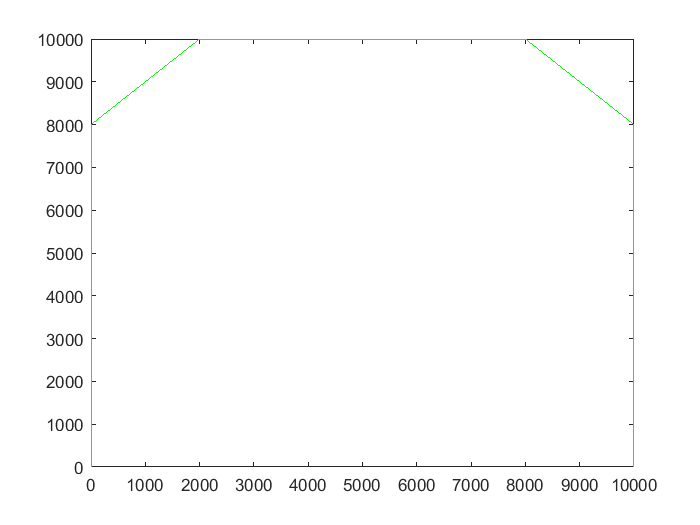

% точки оснвого конутра
pl_x(1) = 0;
pl_z(1) = 0;
pl_x(2) = 0;
pl_z(2) = 10000;
pl_x(3) = 10000;
pl_z(3) = 10000;
pl_x(4) = 10000;
pl_z(4) = 0;

% радиус окружностей
R = 2000;
R_phi = 90;

% точки вспомогат контура
d_as = R/2;
pli_x(1) = d_as;
pli_z(1) = 0;
pli_x(2) = d_as;
pli_z(2) = pl_z(2) - d_as;
pli_x(3) = pl_x(3) - d_as;
pli_z(3) = pl_z(3) - d_as;
pli_x(4) = pl_x(4) - d_as;
pli_z(4) = 0;

centr_cir_x(1) = pl_x(2) + R;
centr_cir_z(1) = pl_z(2) - R;
centr_cir_x(2) = pl_x(3) - R;
centr_cir_z(2) = pl_z(3) - R;

% основной контур с учетом окружностей
pl_new_x(1) = pl_x(1);
pl_new_z(1) = pl_z(1);
pl_new_x(2) = pl_x(2);
pl_new_z(2) = pl_z(2) - R;
pl_new_x(3) = pl_x(2) + R;
pl_new_z(3) = pl_z(2);
pl_new_x(4) = pl_x(3) - R;
pl_new_z(4) = pl_z(3);
pl_new_x(5) = pl_x(3);
pl_new_z(5) = pl_z(3) - R;
pl_new_x(6) = pl_x(4);
pl_new_z(6) = pl_z(4);

plot(pl_new_x, pl_new_z, 'g')

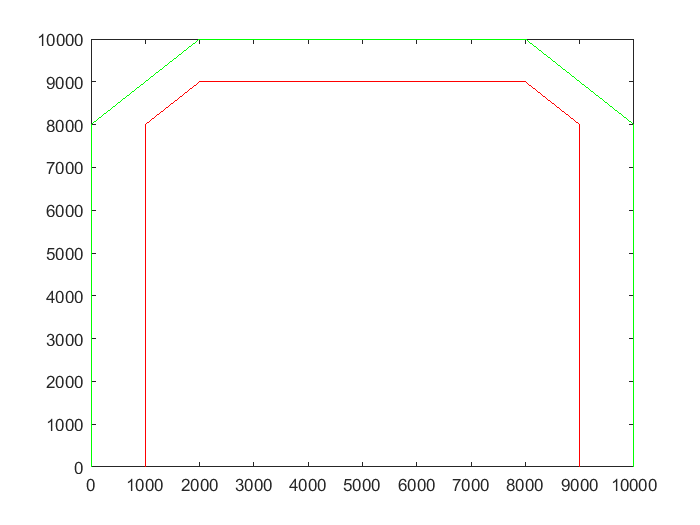


pli_new_x(1) = pl_new_x(1) + d_as;
pli_new_z(1) = pl_new_z(1);
pli_new_x(2) = pl_new_x(2) + d_as;
pli_new_z(2) = pl_new_z(2);
pli_new_x(3) = pl_new_x(3);
pli_new_z(3) = pl_new_z(3) - d_as;
pli_new_x(4) = pl_new_x(4);
pli_new_z(4) = pl_new_z(4) - d_as;
pli_new_x(5) = pl_new_x(5) - d_as;
pli_new_z(5) = pl_new_z(5);
pli_new_x(6) = pl_new_x(6) - d_as;
pli_new_z(6) = pl_new_z(6);

% центр новой окружности равен старой
R2 = R/2;
centr_i_cir_x(1) = centr_cir_x(1);
centr_i_cir_z(1) = centr_cir_z(1);
centr_i_cir_x(2) = centr_cir_x(2);
centr_i_cir_z(2) = centr_cir_z(2);

plot(pl_new_x, pl_new_z, 'g', pli_new_x, pli_new_z, 'r')



% в длинах волн
pl_x = pl_x/lambda;
pl_z = pl_z/lambda;
pli_x = pli_x/lambda;
pli_z = pli_z/lambda;
pl_new_x = pl_new_x/lambda;
pl_new_z = pl_new_z/lambda;
pli_new_x = pli_new_x/lambda;
pli_new_z = pli_new_z/lambda;
centr_cir_x = centr_cir_x/lambda;
centr_cir_z = centr_cir_z/lambda;
centr_i_cir_x = centr_i_cir_x/lambda;
centr_i_cir_z = centr_i_cir_z/lambda;
R = R/lambda;
R2 = R2/lambda;

% N_i = 16; % количество точек на ВИ
N_ci = 4; % количество точек на окружности ВИ

% другой способ выбора N-i
l1 = sqrt((pl_new_x(1) - pl_new_x(2))^2 + (pl_new_z(1) - pl_new_z(2))^2);
dx_i = 2*R*sind(R_phi/N_ci/2);
N_i = floor(l1/dx_i)

N_i = 10


N_l = N_i; % количество точек на основном контуре
N_cl = N_ci; % количество точек на окружности основного контура
N_l_DE = 2*N_l;
N_c_DE = 2*N_cl;

% вывод ДХ
% печать разных dx

disp('dx12')

dx12


disp(pli_new_z(2)/N_i)

    0.0800



disp('dx23')

dx23


disp(2*R2*sind(R_phi/N_ci/2))

    0.0390




[x12,z12,x23,z23,x34,z34,x45,z45,x56,z56] = deal(0);
[tx12,tx23,tx34,tx45,tx56,tx67,tx78,tx89,tx910,tx1011,...
 tz12,tz23,tz34,tz45,tz56,tz67,tz78,tz89,tz910,tz1011] = deal(0);
[dx12,dx23,xd34,dx45,dx56,dx67,dx78,dx89,dx910,dx1011,dx1112] = deal(0);

step12 = pl_new_z(2)/N_l;
step34 = (pl_new_x(4)-pl_new_x(3))/N_l;

for i = 1 : N_l
    x12(i) = 0;
    z12(i) = (i-0.5)*step12;
    x34(i) = pl_new_x(3) + (i-0.5)*step34;
    z34(i) = pl_new_z(3);
    x56(i) = pl_new_x(5);
    z56(i) = pl_new_z(5) - (i-0.5)*step12;
    
    dx12(i) = step12;
    dx34(i) = step34;
    dx56(i) = step12;
    
    tx12(i) = 0;
    tz12(i) = 1;
    tx34(i) = 1;
    tz34(i) = 0;
    tx56(i) = 0;
    tz56(i) = -1;
    tx67(i) = 0;
    tz67(i) = -1;
    tx89(i) = -1;
    tz89(i) = 0;
    tx1011(i) = 0;
    tz1011(i) = 1;
end

%%% Построим дугу окружности 1
for i = 1 : N_cl
    phid_step = R_phi/N_cl;
    t1 = phid_step*(i-0.5);
    x23(i) = R*cosd(-t1+180) + centr_cir_x(1);
    z23(i) = R*sind(-t1+180) + centr_cir_z(1);
    dx23(i) = 2*R*sind(phid_step/2);
    tx23(i) = sind(phid_step*i);
    tz23(i) = cosd(phid_step*i);
    tx910(i) = sind(-90 + phid_step*i);
    tz910(i) = cosd(-90 + phid_step*i);
end

%%% Построим дугу окружности 2
for i = 1 : N_cl
    phid_step = R_phi/N_cl;
    t2 = phid_step*(i-0.5);
    x45(i) = R*cosd(-t2+90) + centr_cir_x(2);
    z45(i) = R*sind(-t2+90) + centr_cir_z(2);
    dx45(i) = 2*R*sind(phid_step/2);
    tx45(i) = sind(90 + phid_step*i);
    tz45(i) = cosd(90 + phid_step*i);
    tx78(i) = sind(180 + phid_step*i);
    tz78(i) = cosd(180 + phid_step*i);
    
end


x_midle = horzcat(x12,x23,x34,x45,x56);
x_midle = horzcat(x_midle, flip(x_midle));
z_midle = horzcat(z12,z23,z34,z45,z56);
z_midle = horzcat(z_midle, flip(-z_midle));
dx = horzcat(dx12,dx23,dx34,dx45,dx56);
dx = horzcat(dx, flip(dx));

N_l_all = length(x_midle); %%%

tx = horzcat(tx12,tx23,tx34,tx45,tx56,tx67,tx78,tx89,tx910,tx1011);
tz = horzcat(tz12,tz23,tz34,tz45,tz56,tz67,tz78,tz89,tz910,tz1011);

для ВИ

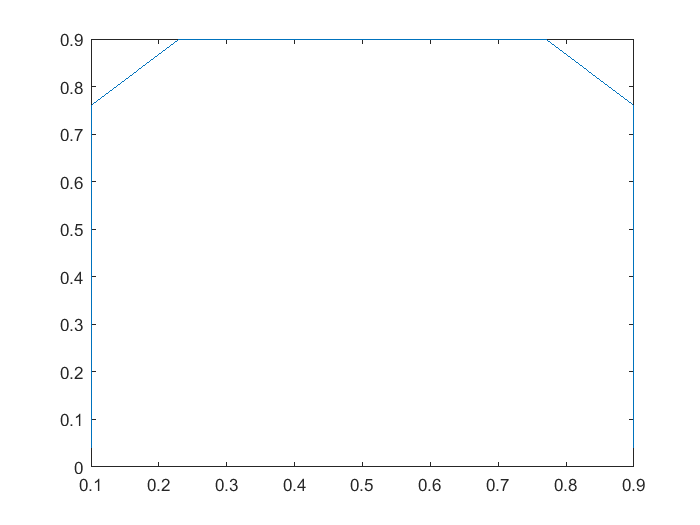

[x12,z12,x23,z23,x34,z34,x45,z45,x56,z56] = deal(0);

step12 = pli_new_z(2)/N_i;
step34 = (pli_new_x(4)-pli_new_x(3))/N_i;

for i = 1 : N_i
    x12(i) = pli_new_x(1);
    z12(i) = (i-0.5)*step12;
    x34(i) = pli_new_x(3) + (i-0.5)*step34;
    z34(i) = pli_new_z(3) ;
    x56(i) = pli_new_x(5);
    z56(i) = pli_new_z(5) - (i-0.5)*step12;
end

plot([x12, x34, x56], [z12, z34, z56])

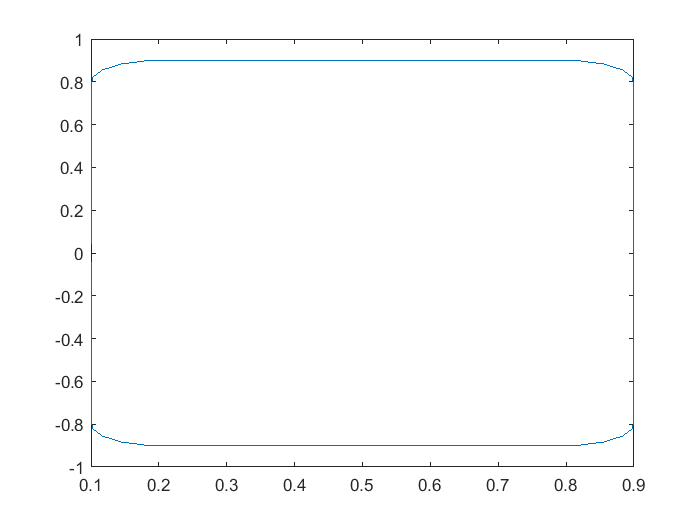

%%% Построим дугу окружности 1


for i = 1 : N_ci
    phid_step = R_phi/N_ci;
    t1 = phid_step*(i-0.5);
    x23(i) = R2*cosd(-t1+180) + centr_i_cir_x(1);
    z23(i) = R2*sind(-t1+180) + centr_i_cir_z(1);
end

%%% Построим дугу окружности 2
for i = 1 : N_ci
    phid_step = R_phi/N_ci;
    t2 = phid_step*(i-0.5);
    x45(i) = R2*cosd(-t2+90) + centr_i_cir_x(2);
    z45(i) = R2*sind(-t2+90) + centr_i_cir_z(2);
end


x_midle_i = horzcat(x12,x23,x34,x45,x56);
x_midle_i = horzcat(x_midle_i, flip(x_midle_i));
z_midle_i = horzcat(z12,z23,z34,z45,z56);
z_midle_i = horzcat(z_midle_i, flip(-z_midle_i));

N_i_all = length(x_midle_i); %%%

plot(x_midle_i, z_midle_i)

Для невязки

[x12,z12,x23,z23,x34,z34,x45,z45,x56,z56,...
    dx12,dx23,d34,dx45,dx56] = deal(0);
[tx12,tx23,tx34,tx45,tx56,tx67,tx78,tx89,tx910,tx1011,...
 tz12,tz23,tz34,tz45,tz56,tz67,tz78,tz89,tz910,tz1011] = deal(0);

step12 = pl_new_z(2)/N_l_DE;
step34 = (pl_new_x(4)-pl_new_x(3))/N_l_DE;

for i = 1 : N_l_DE-1
    x12(i) = 0;
    z12(i) = i*step12;
    x34(i) = pl_new_x(3) + i*step34;
    z34(i) = pl_new_z(3);
    x56(i) = pl_new_x(5);
    z56(i) = pl_new_z(5) - i*step12;
    
    dx12(i) = step12;
    dx34(i) = step34;
    dx56(i) = step12;
    
    tx12(i) = 0;
    tz12(i) = 1;
    tx34(i) = 1;
    tz34(i) = 0;
    tx56(i) = 0;
    tz56(i) = -1;
    tx67(i) = 0;
    tz67(i) = -1;
    tx89(i) = -1;
    tz89(i) = 0;
    tx1011(i) = 0;
    tz1011(i) = 1;
end

%%% Построим дугу окружности 1
for i = 1 : N_c_DE-1
    phid_step = R_phi/N_c_DE;
    t1 = phid_step*i;
    x23(i) = R*cosd(-t1+180) + centr_cir_x(1);
    z23(i) = R*sind(-t1+180) + centr_cir_z(1);
    dx23(i) = 2*R*sind(phid_step/2);
    tx23(i) = sind(phid_step*i);
    tz23(i) = cosd(phid_step*i);
    tx910(i) = sind(-90 + phid_step*i);
    tz910(i) = cosd(-90 + phid_step*i);
end

%%% Построим дугу окружности 2
for i = 1 : N_c_DE-1
    phid_step = R_phi/N_c_DE;
    t2 = phid_step*i;
    x45(i) = R*cosd(-t2+90) + centr_cir_x(2);
    z45(i) = R*sind(-t2+90) + centr_cir_z(2);
    dx45(i) = 2*R*sind(phid_step/2);
    tx45(i) = sind(90 + phid_step*i);
    tz45(i) = cosd(90 + phid_step*i);
    tx78(i) = sind(180 + phid_step*i);
    tz78(i) = cosd(180 + phid_step*i);
end


x_midle_DE = horzcat(x12,x23,x34,x45,x56);
x_midle_DE = horzcat(x_midle_DE, flip(x_midle_DE));
z_midle_DE = horzcat(z12,z23,z34,z45,z56);
z_midle_DE = horzcat(z_midle_DE, flip(-z_midle_DE));
dx_DE = horzcat(dx12,dx23,dx34,dx45,dx56);
dx_DE = horzcat(dx_DE, flip(dx_DE));

N_DE_all = length(x_midle_DE); %%%

tx_DE = horzcat(tx12,tx23,tx34,tx45,tx56,tx67,tx78,tx89,tx910,tx1011);
tz_DE = horzcat(tz12,tz23,tz34,tz45,tz56,tz67,tz78,tz89,tz910,tz1011);


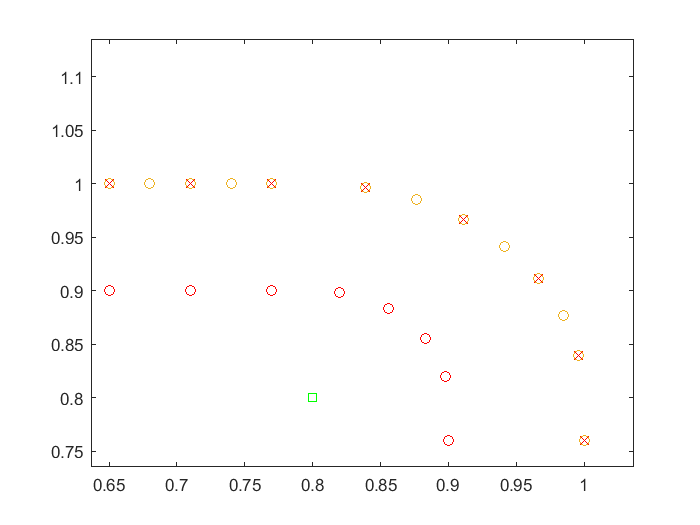

plot(x_midle, z_midle, 'xr',...
     x_midle_i, z_midle_i, 'ro',...
     x_midle_DE, z_midle_DE, 'o', ...
     centr_cir_x(1), centr_cir_z(1),'gs',...
     centr_cir_x(2), centr_cir_z(2),'gs')
 
 
xlim([-0.1+0.8 0.3+0.8])
ylim([0.8 1.2])

#### 1.5. Расчет координат излучателя

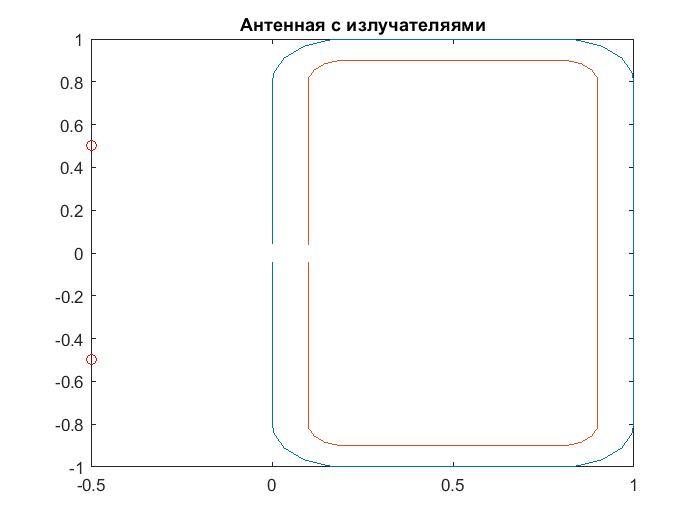

% % % паарметры расположения
l_antenn = 5000/lambda; %%% убрать
h_antenn = 1/2; %%% убрать

% координаты самого излучателя
x1_antenn = - h_antenn;
z1_antenn = pl_x(3) - l_antenn;

% x1_antenn = -(x_midle(1) + 1/2);
% z1_antenn = 0.7;

x2_antenn = x1_antenn;
z2_antenn = -z1_antenn;

plot(x_midle, z_midle, x_midle_i, z_midle_i, x1_antenn, z1_antenn, 'ro', x2_antenn, z2_antenn, 'ro');
% xlim([-2.00 16.00])
% ylim([-16 16.0])
title('Антенная с излучателяями')


% xlim([-1 1])
% ylim([-1 1])

#### 5.1. Падающее поле

% излучаель создает магнитное поле 
Ei = double(zeros(N_l_all,1));
% падающее поле 
for m = 1 : N_l_all
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    
    % растояния 
    r1 = ((xm-x1_antenn)^2 + (zm-z1_antenn)^2);
    r2 = ((xm-x2_antenn)^2 + (zm-z2_antenn)^2);
    
    % Падающее магнитное поле
    Eix = -(zm-z1_antenn)*besselh(1,1,k*r1)/r1...
          -(zm-z2_antenn)*besselh(1,1,k*r2)/r2;
    Eiz = +(xm-x1_antenn)*besselh(1,1,k*r1)/r1...
          +(xm-x2_antenn)*besselh(1,1,k*r2)/r2;
    % Касательное электрическое поле
    Ei(m) = Eix*txm + Eiz*tzm;
end  

#### 5.1. Падающее поле

% % падающее поле ПЛОСКИЙ ФРОН
% 
% % излучаель создает магнитное поле 
% Ei = double(zeros(N_l_all,1));
% % падающее поле 
% for m = 1 : N_l_all
%     xm = x_midle(m);
%     zm = z_midle(m);
%     txm = tx(m);
%     tzm = tz(m);
%     cx = -1i*k*cosd(phi_grad);
%     cz = -1i*k*sind(phi_grad);
%     
%     % Падающее магнитное поле
%     Eix = -1i*sind(phi_grad)*exp(cx*xm+cz*zm);% падающее поле X
%     Eiz = +1i*cosd(phi_grad)*exp(cx*xm+cz*zm);% падающее поле Z
%     % Касательное электрическое поле
%     Ei(m) = Eix*txm + Eiz*tzm;
% end  

#### Сам алгоритм MAS

% Hs = zeros(N,N);
% Es = double(zeros(N_i,N_l));
for m = 1 : N_l_all
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    
    %пробегаемся по всем точкам ВИ
    for n = 1 : N_i_all
        xn = x_midle_i(n);
        zn = z_midle_i(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        rmn = sqrt(xmn^2 + zmn^2);
                
        Ex = -zmn*besselh(1,1,k*rmn)/rmn;
        Ez = +xmn*besselh(1,1,k*rmn)/rmn;
        Es(m,n) = Ex*txm + Ez*tzm;
    end
end

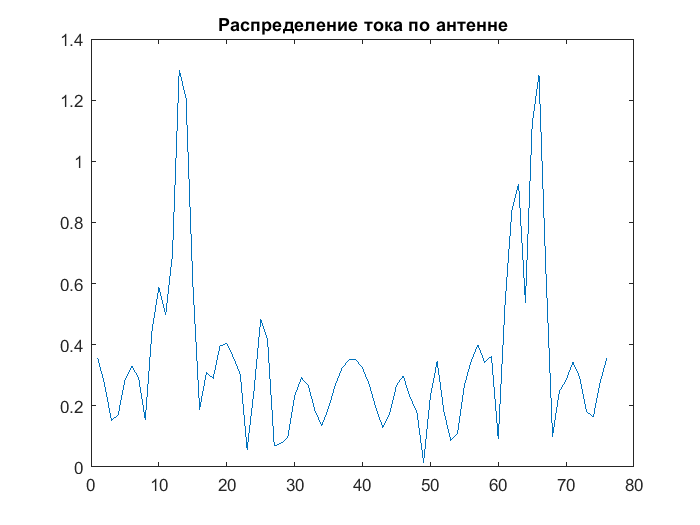

% расчеток токов ВИ 
I=Es\Ei;

plot(1:length(I), abs(I));
title("Распределение тока по антенне")

#### НЕВЯЗКА цилиндр фронт

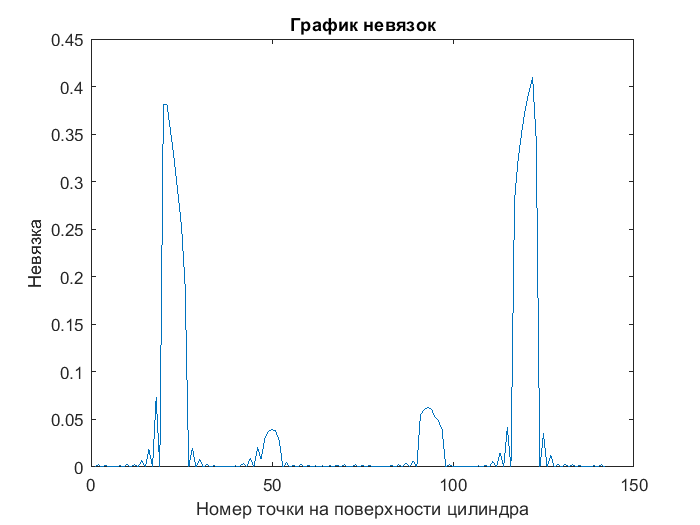

for m = 1 : N_DE_all  
    xm = x_midle_DE(m);
    zm = z_midle_DE(m);
    txm = tx_DE(m);
    tzm = tz_DE(m);
    
    E_DE_sum = 0;    
    for n = 1 : N_i_all
        xn = x_midle_i(n);
        zn = z_midle_i(n);    
                  
        % токи ВИ
        xmn = xm - xn;
        zmn = zm - zn;
        rmn = sqrt(xmn^2 + zmn^2);
            
        Ex = - zmn*besselh(1,1,k*rmn)/rmn;
        Ez = + xmn*besselh(1,1,k*rmn)/rmn;
        Es_DE = Ex*txm + Ez*tzm;
          
        % суммарное поле от ВИ в точке m
        E_DE_sum = E_DE_sum + I(n)*Es_DE;
        
    end
    
    % Падающее магнитное поле
    % растояния 
    r1 = ((xm-x1_antenn)^2 + (zm-z1_antenn)^2);
    r2 = ((xm-x2_antenn)^2 + (zm-z2_antenn)^2);
    
    Eix = -(zm-z1_antenn)*besselh(1,1,k*r1)/r1...
          -(zm-z2_antenn)*besselh(1,1,k*r2)/r2;
    Eiz = +(xm-x1_antenn)*besselh(1,1,k*r1)/r1...
          +(xm-x2_antenn)*besselh(1,1,k*r2)/r2;
    % Касательное электрическое поле
    Ei_DE = Eix*txm + Eiz*tzm;
     
    % cам расчет невязки
    dE(m,1) =  abs(Ei_DE - E_DE_sum);
end    
    
% график для невязки
figure;
plot(1:length(dE),dE);
title('График невязок'); 
xlabel('Номер точки на поверхности цилиндра'); 
ylabel('Невязка');

#### НЕВЯЗКА плоский фронт

% 
% for m = 1 : N_DE_all  
%     xm = x_midle_DE(m);
%     zm = z_midle_DE(m);
%     txm = tx_DE(m);
%     tzm = tz_DE(m);
%     
%     E_DE_sum = 0;    
%     for n = 1 : N_i_all
%         xn = x_midle_i(n);
%         zn = z_midle_i(n);    
%                   
%         % токи ВИ
%         xmn = xm - xn;
%         zmn = zm - zn;
%         rmn = sqrt(xmn^2 + zmn^2);
%             
%         Ex = +zmn*besselh(1,1,k*rmn)/rmn;
%         Ez = -xmn*besselh(1,1,k*rmn)/rmn;
%         Es_DE = Ex*txm + Ez*tzm;
%           
%         % суммарное поле от ВИ в точке m
%         E_DE_sum = E_DE_sum + I(n)*Es_DE;
%         
%     end
%     
%     % Падающее магнитное поле
%     cx = -1i*k*cosd(phi_grad);
%     cz = -1i*k*sind(phi_grad);
%     
%     % Падающее магнитное поле
%     Eix = +1i*sind(phi_grad)*exp(cx*xm+cz*zm);% падающее поле X
%     Eiz = -1i*cosd(phi_grad)*exp(cx*xm+cz*zm);% падающее поле Z
%     % Касательное электрическое поле
%     Ei_DE = Eix*txm + Eiz*tzm;
%      
%     % cам расчет невязки
%     dE(m,1) =  abs(Ei_DE - E_DE_sum);
% end    
%     
% % график для невязки
% figure;
% plot(1:length(dE),dE);
% title('График невязок'); 
% xlabel('Номер точки на поверхности цилиндра'); 
% ylabel('Невязка');